Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         0.68 |          0.2 |          0.0010 |
|       1 |          50 |       00:00:03 |         0.18 |      1.6e-02 |          0.0010 |
|       1 |         100 |       00:00:05 |         0.18 |      1.7e-02 |          0.0010 |
|       1 |         150 |       00:00:06 |         0.19 |      1.9e-02 |          0.0010 |
|       1 |         200 |       00:00:07 |         0.21 |      2.1e-02 |          0.0010 |
|       1 |         250 |       00:00:08 |         0.19 |      1.9e-02 |          0.0010 |
|       1 |         300 |       00:00:10 |         0.19 |      1.8

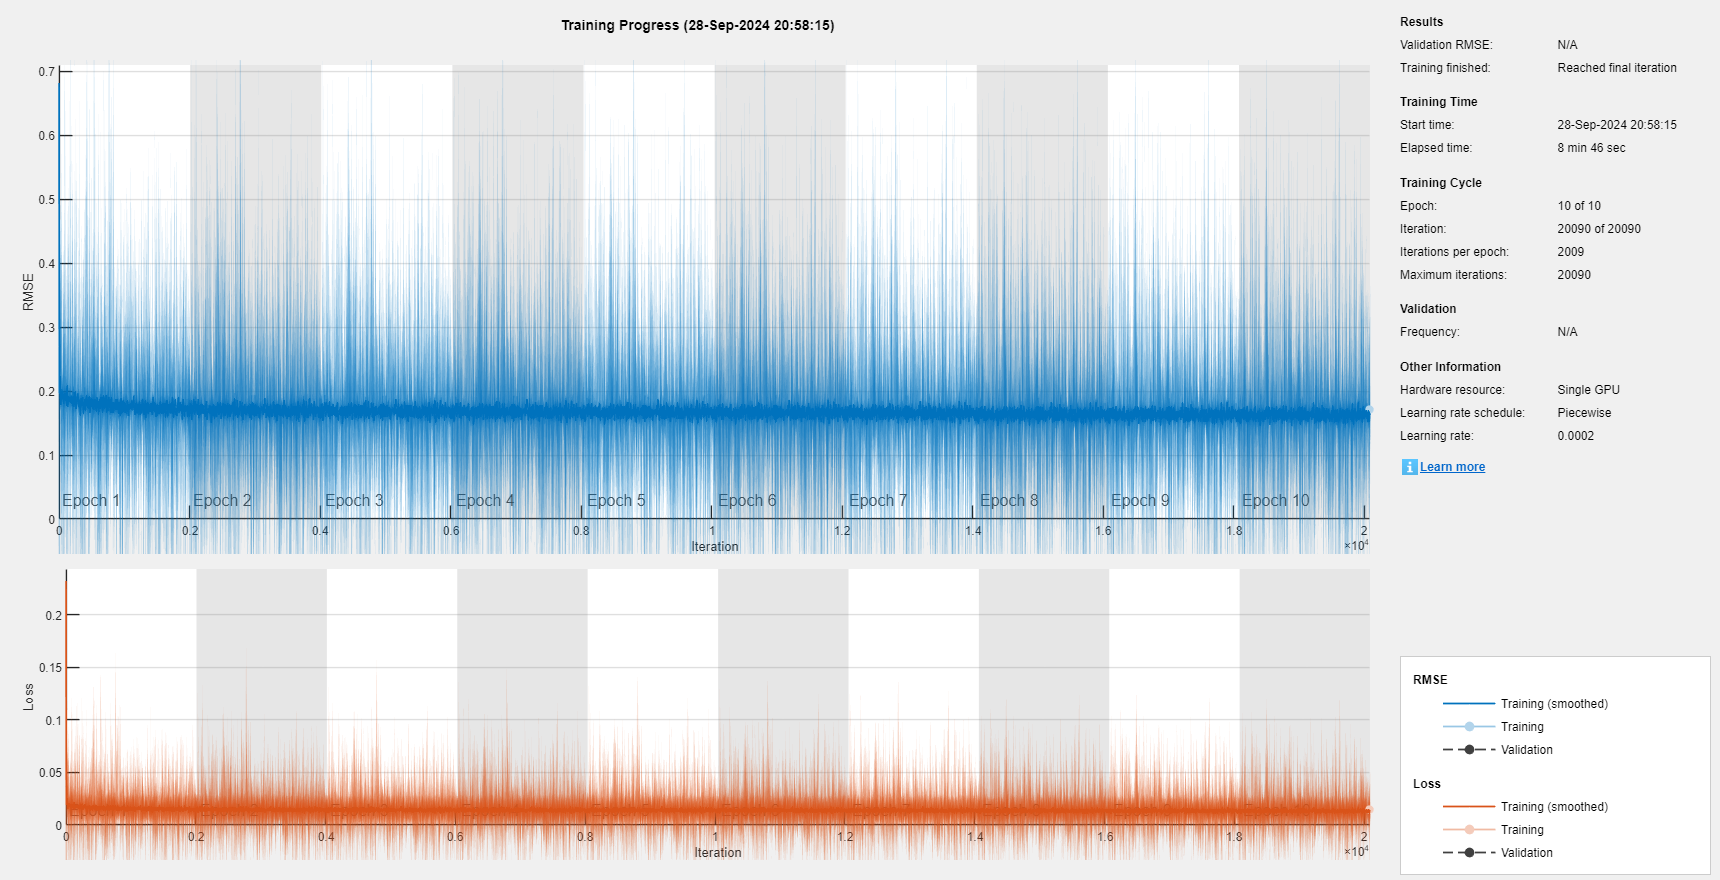

% Clear Workspace for full Reset
clear;

% Import the CSV file
data = readtable('D:\NASA Space Apps 2024\Soil Moisture Dataset\updated_data.csv', 'DatetimeType', 'text');

% Convert time to datetime
data.time = datetime(data.time);

% Sort the data by time
data = sortrows(data, 'time');

% Extract features and target
features = table2array(data(:, {'latitude', 'longitude', 'clay_content', 'sand_content', 'silt_content', 'sm_aux'}));
features(:,2) = features(:,2)*0.0001;
target = data.sm_tgt;

% Normalize the features and target
features_norm = (features - min(features)) ./ (max(features) - min(features));
target_norm = (target - min(target)) ./ (max(target) - min(target));

% Prepare sequences for LSTM
sequenceLength = 30; % Use 30 days of data to predict the next day
numFeatures = size(features, 2);
numSamples = height(data) - sequenceLength;

X = cell(numSamples, 1);
Y = zeros(numSamples, 1);

for i = 1:numSamples
    X{i} = features_norm(i:i+sequenceLength-1, :)';
    Y(i) = target_norm(i+sequenceLength);
end

% Split data into training and testing sets (80% train, 20% test)
numTimeStepsTrain = floor(0.8 * numSamples);
XTrain = X(1:numTimeStepsTrain);
YTrain = Y(1:numTimeStepsTrain);
XTest = X(numTimeStepsTrain+1:end);
YTest = Y(numTimeStepsTrain+1:end);

% Define LSTM network architecture
numHiddenUnits1 = 50;
numHiddenUnits2 = 50;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits1, 'OutputMode', 'sequence')
    lstmLayer(numHiddenUnits2, 'OutputMode', 'last')
    fullyConnectedLayer(1)
    regressionLayer];

% Set training options
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 7, ...
    'LearnRateDropFactor', 0.2, ...
    'Verbose', 1, ...
    'Plots', 'training-progress');

% Train the network
net = trainNetwork(XTrain, YTrain, layers, options);


% Make predictions
YPred = predict(net, XTest);

% Calculate RMSE
rmse = sqrt(mean((YPred - YTest).^2));
fprintf('Test RMSE: %f\n', rmse);

Test RMSE: 0.138889


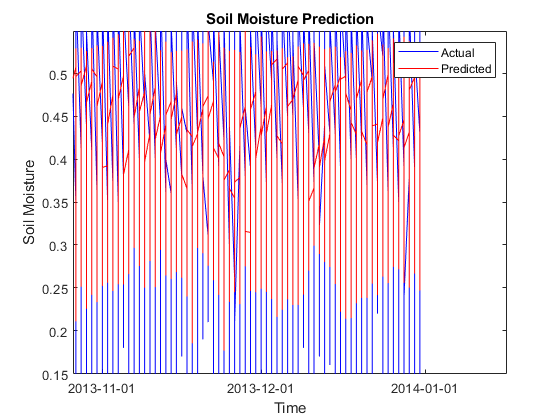


% Denormalize the predictions
YPred_denorm = YPred * (max(target) - min(target)) + min(target);
YTest_denorm = YTest * (max(target) - min(target)) + min(target);

% Plot the results
figure;
plot(data.time(numTimeStepsTrain+sequenceLength+1:end), YTest_denorm, 'b');
hold on;
plot(data.time(numTimeStepsTrain+sequenceLength+1:end), YPred_denorm, 'r');
xlabel('Time');
ylabel('Soil Moisture');
title('Soil Moisture Prediction');
legend('Actual', 'Predicted');
datetick('x', 'yyyy-mm-dd');


% Calculate and print evaluation metrics
mae = mean(abs(YPred_denorm - YTest_denorm));
mape = mean(abs((YTest_denorm - YPred_denorm) ./ YTest_denorm)) * 100;
r2 = 1 - sum((YTest_denorm - YPred_denorm).^2) / sum((YTest_denorm - mean(YTest_denorm)).^2);

fprintf('Mean Absolute Error: %f\n', mae);

Mean Absolute Error: 0.063151


fprintf('Mean Absolute Percentage Error: %f%%\n', mape);

Mean Absolute Percentage Error: 19.941818%


fprintf('R-squared: %f\n', r2);

R-squared: 0.222257


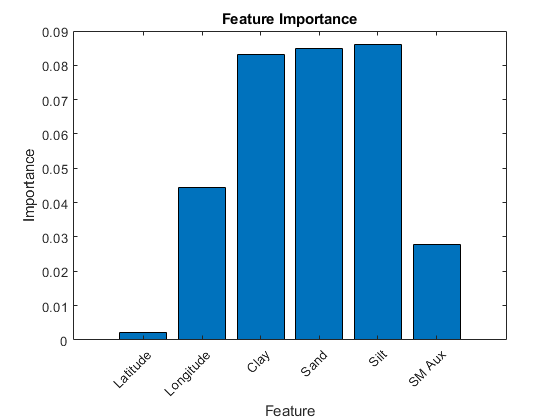


% Plot feature importance
figure;
featureImportance = mean(abs(diff(features_norm)), 1);
bar(featureImportance);
xlabel('Feature');
ylabel('Importance');
title('Feature Importance');
xticklabels({'Latitude', 'Longitude', 'Clay', 'Sand', 'Silt', 'SM Aux'});
xtickangle(45);

% Save the LSTM model to a .mat file
save('D:\NASA Space Apps 2024\SoilMoisturePredictorLSTM.mat', 'net');

% Generate C code for the LSTM model - ERROR!!
codegen predictLSTMModel -args {XNew}

Failed to evaluate '{XNew}' to non-empty array in the base workspace.

Caused by:
    Unrecognized function or variable 'XNew'.
Use help codegen for more information on using this command.


Error using codegen